We try creating a 3D model this time

Extract data

path = "~/AirBeats/MATLAB files/timed_readings.txt";
mpudata = readtable(path);
mpudata.Properties.VariableNames = ["Time", "GyroX", "GyroY", "GyroZ", "AccelX", "AccelY", "AccelZ"]
load orient_dat.mat

Now we do some 3D plot magic. We animate the motion of the sensor with unfiltered data

pp = poseplot
xlabel("North-x (m)")
ylabel("East-y (m)")
zlabel("Down-z (m)");

% calculate position
acceleration = [mpudata.AccelX mpudata.AccelY mpudata.AccelZ]; 
velocity = zeros(391, 3);
for i = 2:391 
        velocity(i,:) = velocity(i-1,:) + (acceleration(i,:)+acceleration(i-1,:))/(2*Fs);
end

position = zeros(391, 3);
for i = 2:391 
        position(i,:) = position(i-1,:) + (velocity(i,:)+velocity(i-1,:))/(2*Fs);
end

% Create orientation matrix
for c = 1:391
    q = quaternion([OrientX(c) OrientY(c) OrientZ(c)], "eulerd", "XYZ", "frame");
    set(pp, Orientation = q, Position = position(i,:));

xlim([-10.00 10.00])
ylim([-10.00 10.00])
zlim([-10.00 10.00])
    drawnow
end

pq = poseplot

pq =   PosePatch with properties:

    Orientation: [1×1 quaternion]
       Position: [0 0 0]

  Show all properties


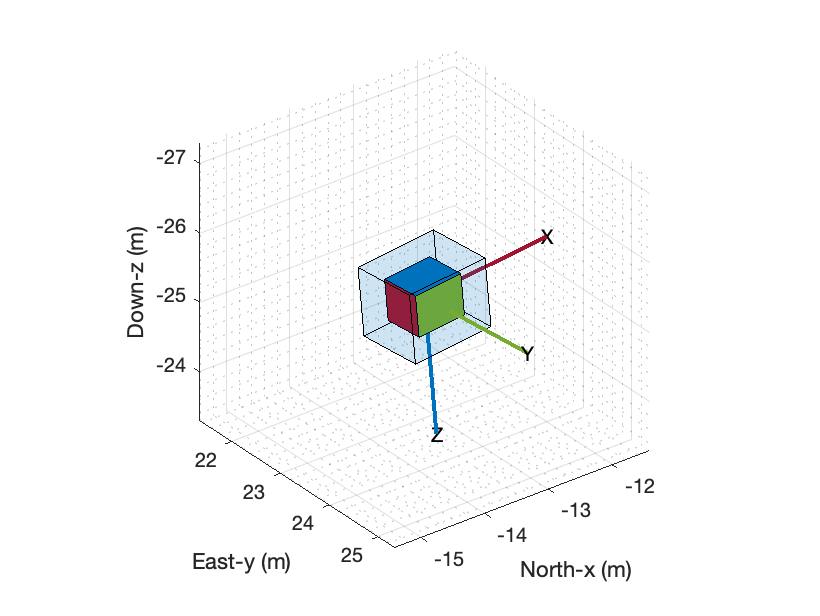

xlabel("North-x (m)")
ylabel("East-y (m)")
zlabel("Down-z (m)")

acceleration = [fax fay faz]; 
velocity = zeros(401, 3);
for i = 2:401 
        velocity(i,:) = velocity(i-1,:) + (acceleration(i,:)+acceleration(i-1,:))/(2*Fs);
end

position = zeros(401, 3);
for i = 2:401
        position(i,:) = position(i-1,:) + (velocity(i,:)+velocity(i-1,:))/(2*Fs);
end

% Create orientation matrix
for c = 1:401
    r = quaternion([fx(c) fy(c) fz(c)], "eulerd", "XYZ", "frame");
    set(pq, Orientation = r, Position = position(i,:));
    drawnow
end

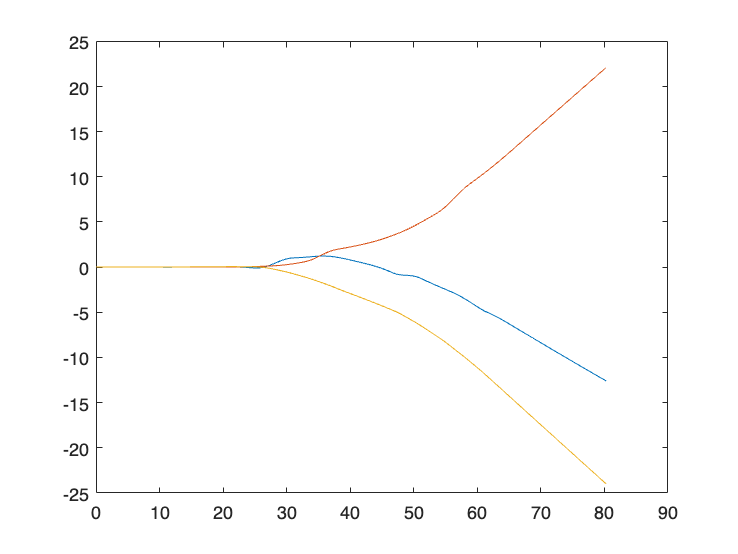



plot(mpudata.Time,position(1:391,:))